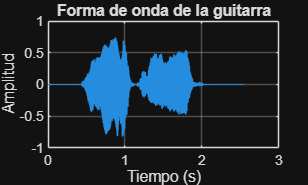

%% Importar audio
[a, fs] = audioread("394550__skegg__oh-xanaina.wav");

% Duración del sonido
d = length(a) / fs;

% Determinar si el audio es mono o estéreo
if size(a, 2) == 1
    % Si el audio es mono, no es necesario promediar canales
    a_m = a.';  % Transponer para convertirlo en fila
else
    % Si el audio es estéreo, combinar los dos canales
    a_m = 0.5 * (a(:,1) + a(:,2)).';  % Promedio de los dos canales
end

% Forma de onda gráfica
t = linspace(0, d, length(a_m));  % para que sea columna

% Graficar
figure()
plot(t, a_m);
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;
title('Forma de onda de la guitarra');

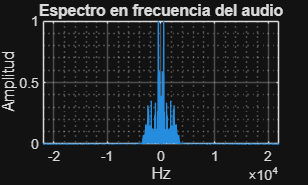


%% Dominio de la frecuencia 
A_m = fftshift(fft(a_m));

% Por el teorema de Nyquist, va a tener el siguiente rango. 
% Eje de frecuencias para corregir nuestro espectro y hacer que vaya desde
% cero, usamos el siguiente comando
f = linspace(-fs/2, fs/2, length(A_m));

% Necesitamos la magnitud, dado que la transformada nos arroja un número complejo
mag_A = abs(A_m);

figure();
plot(f, mag_A/max(mag_A));
title("Espectro en frecuencia del audio");
xlabel("Hz");
ylabel("Amplitud");
grid on, grid minor;

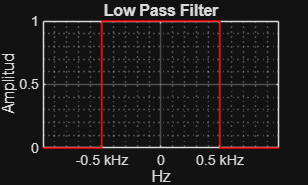

% Normalizamos la magnitud dividiendo por su valor máximo

%% Filtro Ideal

fc = 500;  % Frecuencia de corte (500 Hz)

% Low Pass: el 1 multiplica por cada vez que los elementos de f
% cumplan con esta condición
lpf = 1.*(abs(f)<=fc);
figure();
plot(f, lpf , 'r');
title("Low Pass Filter");
xlabel("Hz");
ylabel("Amplitud");
grid on, grid minor;
% Configuración automática de las etiquetas del eje x
xticks([-fc, 0, fc]); % Posiciones de los ticks
xticklabels({[num2str(-fc/1000), ' kHz'], '0', [num2str(fc/1000), ' kHz']}); % Etiquetas dinámicas

% Ajustar los límites del eje x
xlim([-fc - 500, fc + 500]); % Rango de -fc-100 a fc+100

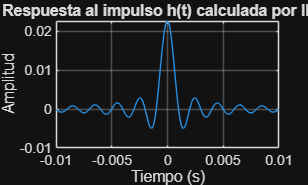


%% Calcular h(t) a partir del filtro en frecuencia (lpf)
% 1. Reordenar el filtro para la transformada inversa
lpf_shifted = ifftshift(lpf);  % Revertir el fftshift

% 2. Calcular la transformada inversa de Fourier
h_t = real(ifft(lpf_shifted));  % Tomar la parte real

% 3. Centrar la respuesta al impulso
h_t = fftshift(h_t);

% 4. Crear vector de tiempo para h(t)
N = length(h_t);
t_h = (-N/2:N/2-1) * (1/fs);  % Vector de tiempo centrado en 0

% 5. Seleccionar una ventana de tiempo para visualización (-10ms a 10ms)
t_window = 0.01;  % 10 milisegundos
idx = find(t_h >= -t_window & t_h <= t_window);

% Graficar h(t)
figure;
plot(t_h(idx), h_t(idx));
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Respuesta al impulso h(t) calculada por IFFT');
grid on;

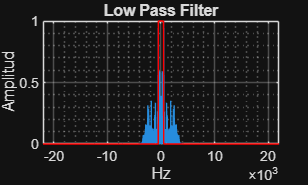


%% Filtro y audio gráfico (resto del código se mantiene igual)
figure();
plot(f, mag_A/max(mag_A));
hold on;
plot(f, lpf , 'r');
title("Low Pass Filter");
xlabel("Hz");
ylabel("Amplitud");
grid on, grid minor;
ax= gca;
ax.XAxis.Exponent=3;

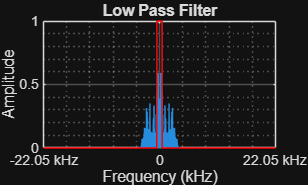


%% Grafica etiquetando la maxima frecuencia
figure();
plot(f, mag_A/max(mag_A)); % Graficar la señal original
hold on;
plot(f, lpf, 'r'); % Graficar la señal filtrada en rojo
title("Low Pass Filter");
xlabel("Frequency (kHz)");
ylabel("Amplitude");
grid on, grid minor;

% Obtener la frecuencia mínima y máxima
f_min = min(f); % Frecuencia mínima
f_max = max(f); % Frecuencia máxima

% Margen adicional para los límites
margin = 100; % Ajustar según necesidad

% Ajustar los límites del eje x
xlim([f_min - margin, f_max + margin]); % Limitar el rango de frecuencias

% Convertir las frecuencias a kHz
f_min_kHz = f_min / 1000; % Frecuencia mínima en kHz
f_max_kHz = f_max / 1000; % Frecuencia máxima en kHz

% Configurar los ticks y etiquetas dinámicamente
xticks([f_min, 0, f_max]); % Posiciones de los ticks
xticklabels({[num2str(f_min_kHz), ' kHz'], '0', [num2str(f_max_kHz), ' kHz']}); % Etiquetas dinámicas

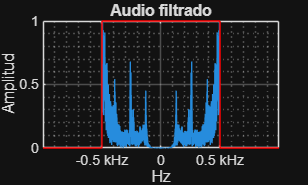


%% Filtrado
A_lpf = A_m .* lpf;

figure();
plot(f, abs(A_lpf)/max(abs(A_lpf)));
hold on;
plot(f, lpf , 'r');
title("Audio filtrado");
xlabel("Hz");
ylabel("Amplitud");
grid on, grid minor;

% Configuración automática de las etiquetas del eje x
xticks([-fc, 0, fc]); % Posiciones de los ticks
xticklabels({[num2str(-fc/1000), ' kHz'], '0', [num2str(fc/1000), ' kHz']}); % Etiquetas dinámicas

% Ajustar los límites del eje x
xlim([-fc - 500, fc + 500]); % Rango de -fc-100 a fc+100

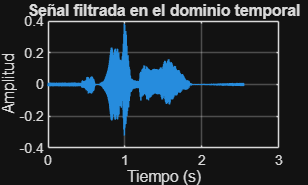


%% Inverse FFT
a_lpf = ifft(fftshift(A_lpf));
a_lpf = real(a_lpf);

% Tiempo asociado a la señal filtrada
t_filtered = linspace(0, d, length(a_lpf));

% Graficar la señal filtrada en el dominio temporal
figure();
plot(t_filtered, a_lpf);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal filtrada en el dominio temporal');
grid on;


%% Reproducir audio
% Reproducir audio original
disp("Reproduciendo audio original...");

Reproduciendo audio original...


sound(a, fs);
pause(d + 2);  % Pausar por la duración del audio original más 2 segundos de margen

% Reproducir audio filtrado
disp("Reproduciendo audio filtrado...");

Reproduciendo audio filtrado...


sound(a_lpf, fs);

%% Guardar archivo filtrado
filename = 'skegg_filtrado.wav';  % Nombre del archivo de salida
audiowrite(filename, a_lpf.', fs);   % Importante: transponer a_lpf para que sea columna